## Question 2

setting constants,

rng(0);
lamda_true = 5;
alpha_prior = 5.5;
beta_prior = 1;
m = 150;
mle_lamda = zeros(m,10);
bayesian_lamda = zeros(m,10);
curr = 1;

for n_value = [5,10,20,40,60,80,100,500,1000,10000]  
    for exp_num = 1:1:m
    data = rand(1,n_value);
    data = (-1.*log(data))./lamda_true;


$$$$ L(y_{1}, y_{2}...y_{n}| \lambda) = \prod_{i = 1}^{n}\lambda e^{-\lambda y_{i}}$$$$



$$$$\therefore L(y_{1}, y_{2}...y_{n}| \lambda) = \lambda ^{n} e^{-\lambda \Sigma y_{i}}$$}$$


To get maximum likelihood:


$$$$\frac{d}{d\lambda}L(y_{1}, y_{2}...y_{n}| \lambda) = 0$$$$



$$$$\frac{d}{d\lambda}\lambda ^{n} e^{-\lambda \Sigma y_{i}}= 0$$$$



$$$$n \lambda^{n-1}e^{-\lambda \Sigma y_{i}} - \lambda ^{n} e^{-\lambda \Sigma y_{i}}\Sigma y_{i} = 0$$$$



$$$$\hat{\lambda}^{ML} = \frac{n}{\Sigma y_{i}}$$$$


    mle_lamda(exp_num,curr) = n_value./(sum(data));

To get posterior mean we proceed as follows:


$$$$Posterior \propto Prior * Likelihood $$$$



$$$$\therefore Posterior \propto \frac{\beta^{\alpha}}{\Gamma({\alpha})} \lambda^{\alpha - 1} e^{-\beta \lambda} * \lambda ^{n} e^{-\lambda \Sigma y_{i}} $$$$



$$$$\therefore Posterior \propto  \frac{\beta^{\alpha}}{\Gamma({\alpha})}\lambda^{n + \alpha - 1}e^{-\lambda( \beta + \Sigma y_{i})}$$$$



$$$$Posterior \sim Gamma(\lambda;n+ \alpha, \beta +\Sigma y_{i} )$$$$


It means posterior is also gamma distribution with parameters $$n+ \alpha $$ and $$\beta +\Sigma y_{i}$$

So the posterior mean=      $$$\hat{\lambda}^{PosteriorMean} = \frac{n + \alpha}{\beta + \Sigma y_{i}}$$$

    bayesian_lamda(exp_num,curr) = (n_value + alpha_prior)./(beta_prior + sum(data));
    end
    curr = curr+1;
end

Calculation of errors,

relative_error_in_mle = abs(mle_lamda - lamda_true)./lamda_true;
relative_error_in_bayesian = abs(bayesian_lamda - lamda_true)./lamda_true;
n_value = [5,10,20,40,60,80,100,500,1000,10000];

Plotting of boxplots,

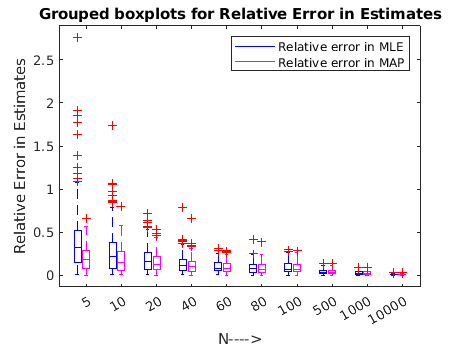

figure ;
boxplot(relative_error_in_mle,'Colors','b','Labels',n_value,'Widths',0.2,'Positions',(1:numel(n_value)))
hold on;
boxplot(relative_error_in_bayesian,'Colors','m','Labels',n_value,'Widths',0.2,'Positions',(1:numel(n_value))+0.25)
xlabel("N---->")
ylabel("Relative Error in Estimates")
title("Grouped boxplots for Relative Error in Estimates")
plot(NaN,1,'Color','b')
plot(NaN,1,'Color','m')
legend({'Relative error in MLE','Relative error in MAP'})